Input variables

name = "User5";
activity = "LocationB";
type = "Normal";
thres_low = 22;
thres_real = 22;

Main computation

% read raw data from csv
filename_raw = strcat('normal-dataset\', name, '_', activity, '_', type, '.csv');
data_raw = xlsread(filename_raw);
accel_raw = data_raw(:,2:4);
gyro_raw = data_raw(:,5:7);

[rawrow,~] = size(accel_raw);

% FIXME: vectorize the composition computation
% accel composition
accel_composed = [];
for i = 1:rawrow
    accel_composed = [accel_composed sqrt(accel_raw(i,1)^2 + accel_raw(i,2)^2 + accel_raw(i,3)^2)];
end 

% gyro composition
gyro_composed = [];
for i = 1:rawrow 
    gyro_composed = [gyro_composed sqrt(gyro_raw(i,1)^2 + gyro_raw(i,2)^2 + gyro_raw(i,3)^2)];
end

Find peaks and generate plot

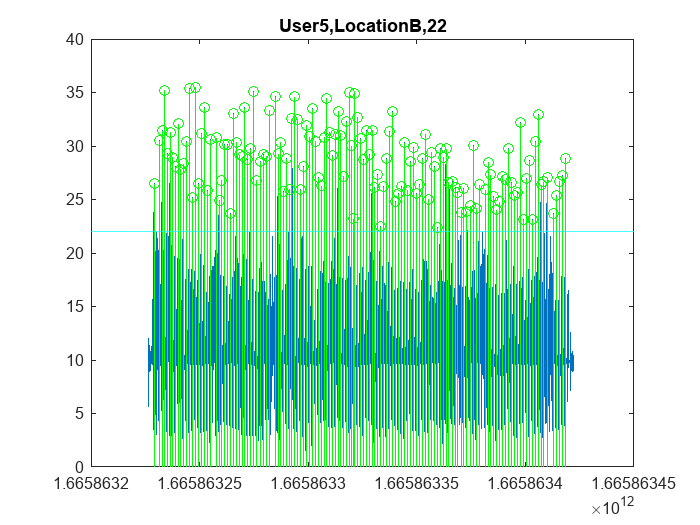

% find acceleration peaks
[pks,~,pidx,~] = peakdet(accel_composed', thres_low, 'th',50); % FIXME: determine threshold (2nd arg) DYNAMICALLY
[pidxRow,~] = size(pidx);

% plot: accelerometer, peaks vs. time
time = data_raw(:,1); 
figure;
plot(time, accel_composed)
hold on
stem(time(pidx),pks,'g') 
yline(thres_real, 'c')
title(strcat(name, ', ', activity, ', ', num2str(thres_real)))
hold off

Write to image files

% loop over time segments, writing to image file
for d = 1:pidxRow
    if (pidx(d)-63 > 0)
        accel_window = accel_composed(pidx(d)-63:pidx(d)+64);
        gyro_window = gyro_composed(pidx(d)-63:pidx(d)+64);
    end % add an else?

    combined_window = [accel_window; gyro_window];
    imname = strcat('images\varied-threshold\', name, '\', name, '_', activity, '_', type, '_', num2str(d), '.png');
    imwrite(combined_window, imname);
end